# Direction Fields & Phase Planes

Understanding the behavior of two dimensional systems can often best be achieved graphically. A good method is to plot the directions of the vectors and this leads us to direction fields and phase planes

## Direction Fields

A direction field is basically a plot of the direction and magnitude of the derivative of an ordinary differential equation on a grid of points. The paths followed by different solutions (determined by different initial conditions) are curves that are tangent to these vectors, so it becomes easy to visualize the trajectories and rates of the evolution of different solutions. Let's look at the diretion field for the differntial equation 


$$\frac{dy}{dx} = x^3 - 3xy$$


using Matlab — we've writtena function that does all the hard work but is general enough that it can be used for different differential equations. 

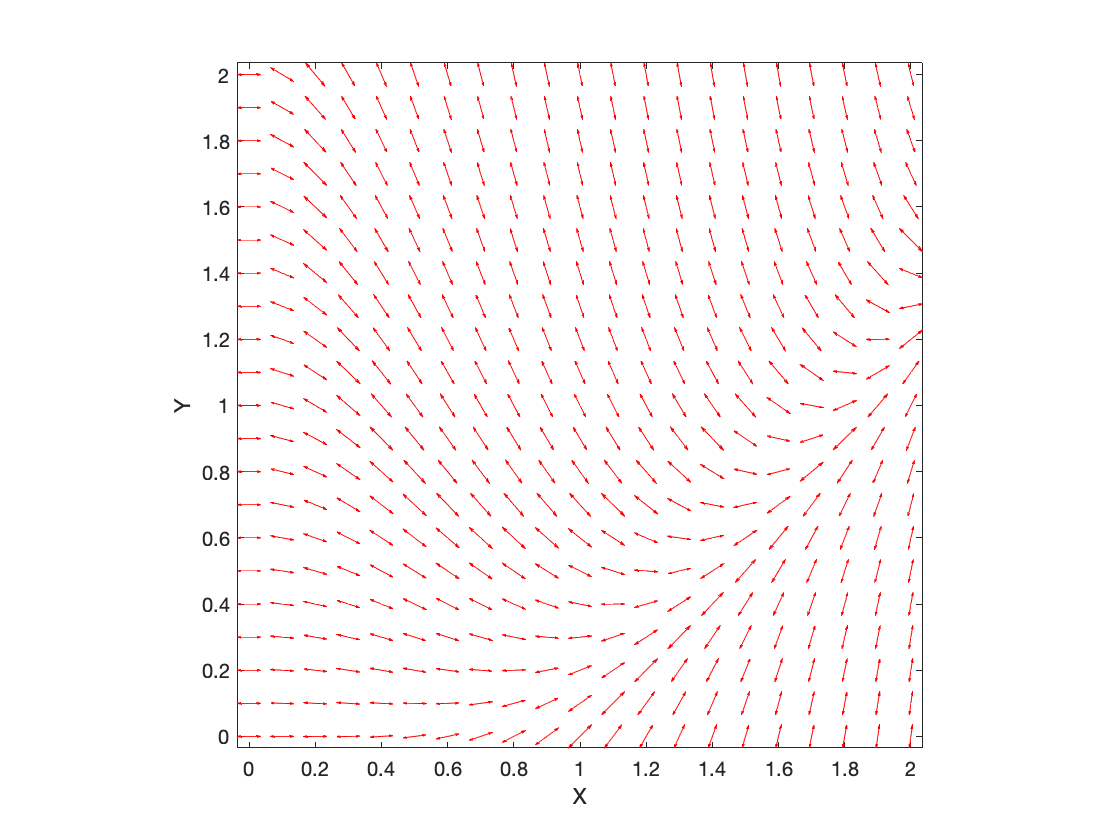

% Frist define a function that calculates the right hand side of the
% differential equation
fcn = @(x,y) x.^3 - 3*x.*y;

% To set up the grid we need to specify the x and y limits we want to look
% at and the spacing between the grid points. The vectors will then be
% calculated at the intersections of the grid lines. 
x_range = [0 2];
y_range = [0 2];

del_x = 0.1;
del_y = 0.1;

% Now calculate and plot the direction field. 
[x_values, y_values, scale_factor, dydx] = DirectionFieldMMMEES(@(x,y) x.^3 - 3*x.*y, x_range, del_x, y_range, del_y);

We can see from this example that trajectories converge onto a single direction as the solutions to the equation evolves. 

## Phase plane

For two-dimensional systems of differential equations we end up plotting the phase plane, but the idea is very similar. At each grid point we plot the vector whose components are the derivatives of the two variables. For example, let's look at the phase plane of a simple oscillator


$$\frac{d^2y}{dt^2} = - \sin(y)$$


The first thing we have to do is to re-write the second-order equation as two first order equations


$$\frac{du}{dt} = v, \qquad \frac{dv}{dt} = -\sin(u)$$


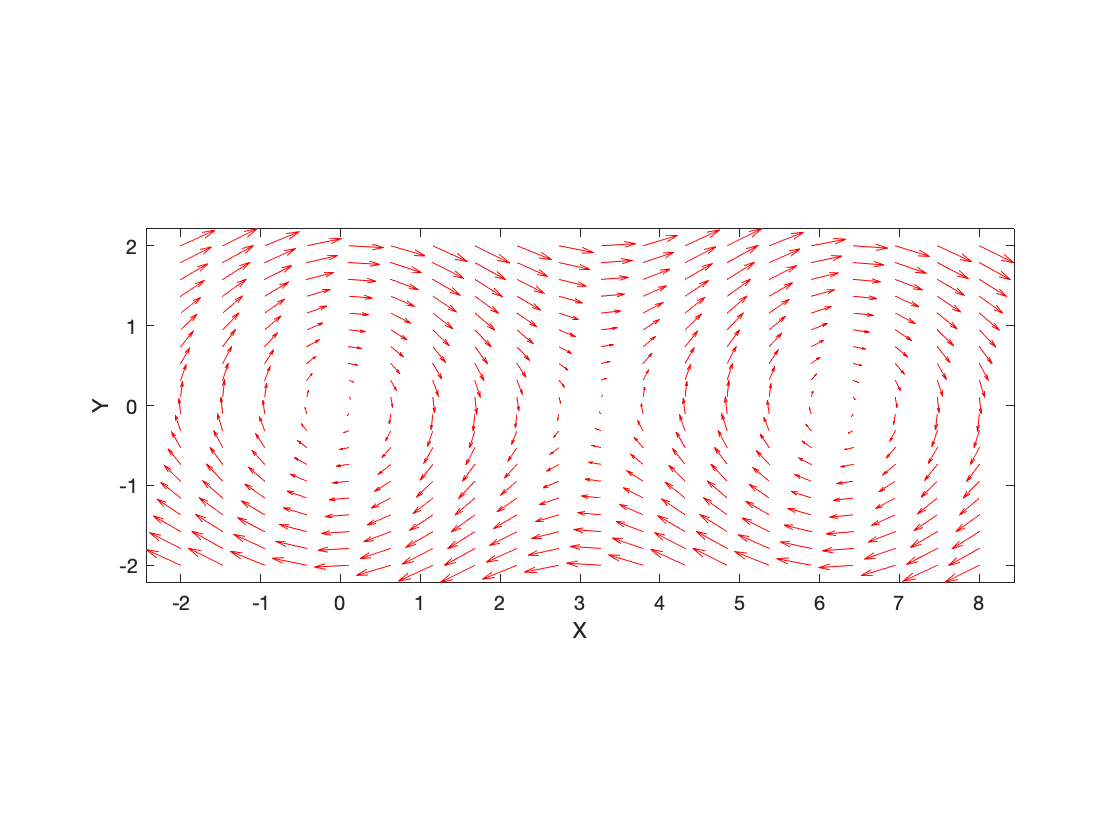

% Create a function defining the differential equation
fcn2 = @(t,u) [u(2); -sin(u(1))];

% Set up the grid limits and interval
x_min = -2;
x_max = 8;
y_min = -2;
y_max = 2;
n_x = 20;
n_y = 20;

% Calculate and plot the phase plane. 
t = PhasePlaneMMEES(fcn2, x_min, x_max, n_x, y_min, y_max, n_y);

 For this example we can easily see the steady states (where the sizes of the derivatives will go to zero) and the periodicity in the solution. We can also see that for some trajectories there are circular paths, but as the amplitude of the oscillation becomes larger, the trajectory continually increases in X. 

***Exercise:**** Calculate and interpret the phase plane of the system*


$$\frac{dx}{dt} = -x + xy,\qquad \frac{dy}{dt} = -y + xy$$
